# Breast Cancer Coimbra SVM MATLAB Classifier

## Dataset Description

The dataset was obtained from the UCI Machine Learning Repisotory : **Breast Cancer Coimbra Data Set** 

It features 116 samples each with 9 attributes or features:

- Age (years) 

- BMI (kg/m2)

- Glucose (mg/dL) 

- Insulin (µU/mL) 

- HOMA

- Leptin (ng/mL) 

- Adiponectin (µg/mL) 

- Resistin (ng/mL) 

- MCP-1(pg/dL) 

Labels: 

- 1=Healthy controls 

- 2=Patients

Its a new attempt at early detection of breast cancer using a simple blood analysis other than commonly used mammogram scans

More information on the dataset [https://archive.ics.uci.edu/ml/datasets/Breast+Cancer+Coimbra](https://archive.ics.uci.edu/ml/datasets/Breast+Cancer+Coimbra)

The highest accuracy so far achieved has been 82.1% after exclusion of two of the features Adiponectin and MCP. However reproducibility of is difficult and thus the average accuracy  is 76.1% using Kfold validation on the entire dataset using a linear SVM excluding 2 features age and MCP.

## Step 1: Dataset Preparation

Here we prepare our data so that it can be fed to the svm accordingly. The data is first loaded from an excel xlsx or csv file and the necessry collumns extracted. The data is also shuffled up so as to avoid any variance or bias problems that may arise.

%The prefix bc means breast cancer diagnostic
%Auto detect import options
opts = detectImportOptions('BC_Coimbra.xlsx');

temp_data = readtable('BC_Coimbra.xlsx',opts); %Read the csv file and store 
%The readtable function automaticaylly removes any collumn headers from the data if present
data = table2cell(temp_data); %Convert our table to a cell array for ease of access

sample_no = size(data,1) %Get the number of all diagnosis by getting the number of rows

sample_no = 116


%Create our X and Y for SVM Training
rand_num = randperm(sample_no); % Permutate numbers upto the number of samples randomly, This works as shuffling our rows

%Load our X with features
X_temp = cell2mat(data(:,1:9)); %Convert it to a matrix and selecting the collumn ranges containing features
X = X_temp(rand_num(1:end),:); %Store accordingly with the random number permutations

noFeatures = size(X,2); % Store the number of features of the dataset

%Load our Y with our classes.
Y_temp = cell2mat(data(:,10));
%Convert our categorical characters as classnames to indexes
Y = Y_temp(rand_num(1:end),:);

## Step 2: Perform Cross Validation  : K-fold 10

To reduce any underfitting or overfitting that may occur during testing, the data is cross validated using K-Fold 5 or 10 times. The folds are stratified ensuring a uniform distribution of each class with in each fold further lowering any data bias that would have been present.

%Validate now the training set using Kfold 10 times
%By stratifying we ensure an equal class distribution in all folds
CV = cvpartition(Y,'KFold',10,'Stratify',true);

## Step 3: Feature Ranking

This steps ranks our feature and creates a feature sets consisting  a given number of all the features from 1 feature to all features of the dataset

We use sequential FS to rank the features and store the ranking order in a logical matrix History

opts = statset('display','iter','UseParallel',true); %Sets the display option
rng(5); %This sets our random state.

fun = @(train_data, train_labels, test_data, test_labels)...
    sum(predict(fitcsvm(train_data, train_labels,'Standardize',true,'KernelFunction','gaussian'), test_data) ~= test_labels);

%Rank our features using Sequential FS forward selection
%Inside history we store the ranking of features
[fs, history] = sequentialfs(fun, X, Y, 'cv', CV, 'options', opts,'nfeatures',noFeatures);

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 3, criterion value 0.310345
Step 2, added column 8, criterion value 0.241379
Step 3, added column 1, criterion value 0.181034
Step 4, added column 2, criterion value 0.163793
Step 5, added column 6, criterion value 0.163793
Step 6, added column 5, criterion value 0.189655
Step 7, added column 4, criterion value 0.215517
Step 8, added column 7, criterion value 0.25
Step 9, added column 9, criterion value 0.293103
Final columns included:  all


## Step 4: Kernel and Feature Selection

This step now analyzes 4 kernel functions performance in regard to a given feature set

rng(3);
bc_Accuracy(noFeatures,6) = 0; %Initializes where we'll store our performance for each feature set and kernel
for count=1:noFeatures
    %MStore our best features
    bc_Accuracy(count,1) = count;
    
    %Linear
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'linear','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,2) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %rbf training
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'rbf','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,3) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Gaussian
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'gaussian','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,4) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto');
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,5) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
    
    %Polynomial power 3
    bc_Model= fitcsvm(X(:,history.In(count,:)),Y,'BoxConstraint',1,'CVPartition',CV,'KernelFunction',...
        'polynomial','Standardize',true,'KernelScale','auto','PolynomialOrder',3);
    %This averages our cross validated models loss. The lower the better the prediction
    % Compute validation accuracy
    bc_Accuracy(count,6) = (1 - kfoldLoss(bc_Model, 'LossFun', 'ClassifError'))*100;
end

## Visualize Results

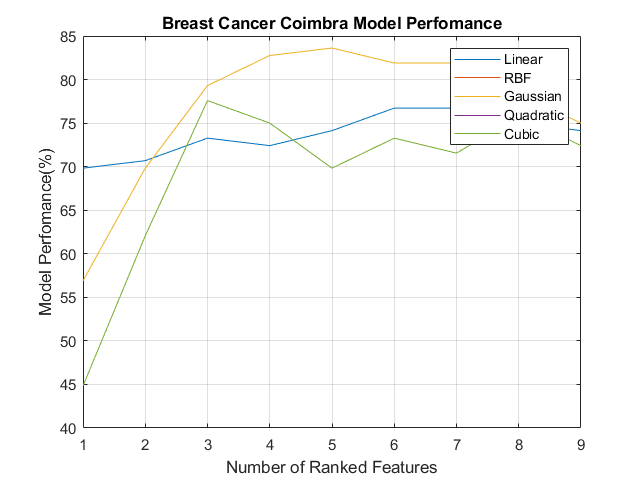

figure
plot(bc_Accuracy(:,2:6))
title('Breast Cancer Coimbra Model Perfomance')
xlabel('Number of Ranked Features')
ylabel('Model Perfomance(%)')
legend('Linear','RBF','Gaussian','Quadratic','Cubic')
grid on;

## Step 5: Model Selection: Best Hyperparameters

We now need to search for the best hyperparameters for the highest accuracy perfomance for the dataset.The following functions will be utilized to tune the SVM parameters C and Kernel function variables We use fitcsvm and train using the best features obtained from step 4. The kernel function is selected from the best perfoming Kernel in the previous step

%The best observed Kernel is a gaussian

%To lower our false negative rate we introduce a cost parameter
% to increase the cost of misclassifying Malignant as Benign
cost.ClassNames = {'2' '1'};
cost.ClassificationCosts = [0 1;1 0];

rng(3);
%For the bayesain optimizer we let it use the defaults but increase its Maximum Objective evaluations to 80

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstrain-|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    | t            |              |
|===============================================================================================================|
|    1 |       1 | Accept |     0.44828 |     0.13586 |     0.26724 |     0.28008 |      0.26653 |    0.0025451 |
|    2 |       1 | Best   |     0.26724 |     0.12149 |     0.26724 |     0.28008 |       5.8664 |       1.3003 |
|    3 |       2 | Accept |     0.34483 |     0.12584 |     0.26724 |     0.28441 |       153.72 |       1.6341 |
|    4 |       2 | Accept |     0.44828 |     0.10258 |     0.26724 |     0.26726 |     0.015849 |     0.079124 |
|  

bc_Model = fitcsvm(X(:,history.In(5,:)),Y,'KernelFunction','gaussian','Cost',cost,'Standardize',true,...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',struct('UseParallel',true,...
    'ShowPlots',false,'MaxObjectiveEvaluations',80,'Repartition',true));

## Step 6: Train a SVM and Evaluate Validation Loss : Kernel Gaussian

%Pass on our X and Y to the SVM classifier.
rng(3); %seeds our random generator allowing for reproducibility of results
%Box Costraint is our penalty factor C, the higher the stricter the hyperplane
constraint = bc_Model.BoxConstraints(1,:);
kernelScale = bc_Model.KernelParameters.Scale;

%using a polynomial kernel
best_Model = fitcsvm(X(:,history.In(4,:)),Y,'CVPartition',CV,'KernelFunction',...
    'gaussian','Standardize',true,'BoxConstraint',constraint,'KernelScale',kernelScale,'Cost',cost);

%This averages our cross validated models loss. The lower the better the prediction
% Compute validation accuracy

validationAccuracy = 87.9310

validationAccuracy = (1 - kfoldLoss(best_Model, 'LossFun', 'ClassifError'))*100
%This averages our cross validated models loss. The lower the better the prediction

bc_ModelLoss = 0.1207

bc_ModelLoss = kfoldLoss(best_Model)

## Step 7: Evaluate the model's perfomance using a confusion Matrix

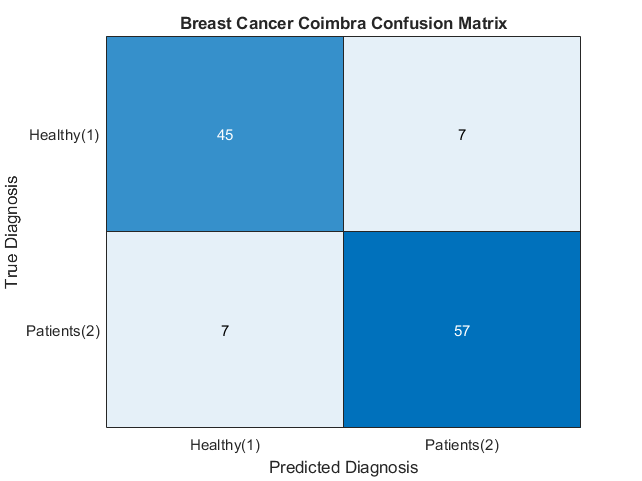

[Y_pred, validationScores] = kfoldPredict(best_Model);
conMat=confusionmat(Y,Y_pred);
%Generate a Confusion Matrix
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat = heatmap(conMat,'Title','Breast Cancer Coimbra Confusion Matrix','YLabel','True Diagnosis','XLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Healthy(1)','Patients(2)'},'YDisplayLabels',{'Healthy(1)','Patients(2)'},'ColorbarVisible','off');

%The following functions compute the precision and F1 Score
precisionFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,2);
recallFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,1);
f1ScoresFunc = @(confusionMat) 2*(precisionFunc(confusionMat).*recallFunc(confusionMat))./(precisionFunc(confusionMat)+recallFunc(confusionMat));
meanF1Func = @(confusionMat) mean(f1ScoresFunc(confusionMat));

falseNegativeRate = (conMat(2,1)/(conMat(2,1)+conMat(2,2)))*100

falseNegativeRate = 10.9375


precision = precisionFunc(conMat)

precision =     0.8654
    0.8906


recall = recallFunc(conMat)

recall =     0.8654    0.7031
    1.0962    0.8906


f1Score = meanF1Func(conMat)

f1Score =     0.9241    0.8332
